# Plotting descent

## Load data

load("..\Data\Schlogl_1_2_descend_1_2straight_500_11-Jul-2022.mat")

load( "..\Data\Selkov_descend_1_1straight_2500_14-Jul-2022.mat")

load( "..\Data\Selkov_descend_1_1straight_4000_14-Jul-2022.mat")

clear all

load("..\Data\Schlogl_1_6_descend_1_1straight_2000_10-Aug-2022.mat")
iter

iter =    309


%load("..\Data\Schlogl_1_2_descend_1_2straight_2000_11-Jul-2022.mat")

num_spec

num_spec =      6


ax_lab = cell(num_spec-1,num_spec);
conf_idx_list = [];
mom_idx_list = [];
ct = 1;
for i = 1:num_spec-1
    for j = i+1:num_spec        
        ax_lab(i,j) = {[j,i]};
        ax_lab(j-1,i) = {[i,j]};
        conf_idx_list = [conf_idx_list (i-1)*num_spec+j];
        mom_idx_list = [mom_idx_list (j-2)*num_spec + i];
        ct = ct + 1;
    end
end
ax_lab

ax_lab = 5×6 cell array
    {[1 2]}    {[2 1]}    {[3 1]}    {[4 1]}    {[5 1]}    {[6 1]}
    {[1 3]}    {[2 3]}    {[3 2]}    {[4 2]}    {[5 2]}    {[6 2]}
    {[1 4]}    {[2 4]}    {[3 4]}    {[4 3]}    {[5 3]}    {[6 3]}
    {[1 5]}    {[2 5]}    {[3 5]}    {[4 5]}    {[5 4]}    {[6 4]}
    {[1 6]}    {[2 6]}    {[3 6]}    {[4 6]}    {[5 6]}    {[6 5]}


conf_idx_list

conf_idx_list =      2     3     4     5     6     9    10    11    12    16    17    18    23    24    30


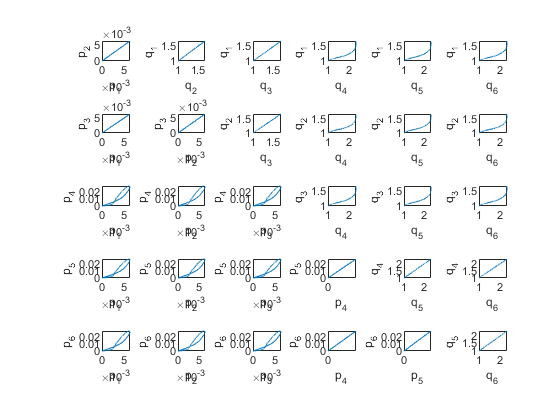

ct = 0;
figure()
hold on
for i = 1:num_spec-1
    for j = i+1:num_spec        
        ct = ct + 1;
        subplot(num_spec-1,num_spec,conf_idx_list(ct))
        plot(PS_traj(:,j),PS_traj(:,i))
        xlabel('q_'+string(j))
        ylabel('q_'+string(i))
        
        subplot(num_spec-1,num_spec,mom_idx_list(ct))
        plot(PS_traj(:,i+num_spec),PS_traj(:,j+num_spec))
        xlabel('p_'+string(i))
        ylabel('p_'+string(j))
        
    end 
end
hold off

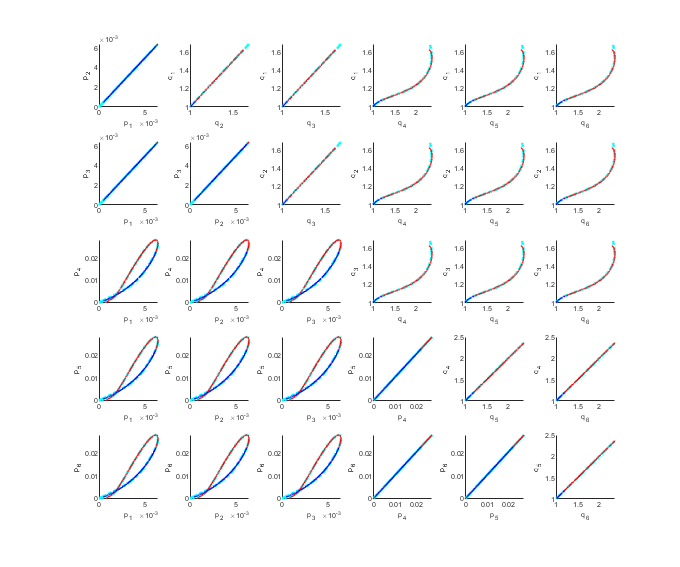

ct = 0;
figure()
hold on
for i = 1:num_spec-1
    for j = i+1:num_spec        
        ct = ct + 1;
        subplot(num_spec-1,num_spec,conf_idx_list(ct))
        hold on
        plot(PS_traj(:,j),PS_traj(:,i),'c-.','LineWidth',2)
        plot(Ham_traj_for(:,j),Ham_traj_for(:,i),'r','LineWidth',1)
        plot(Ham_traj_back(:,j),Ham_traj_back(:,i),'b','LineWidth',1)
        hold off
        xlabel('q_'+string(j))
        ylabel('q_'+string(i))
        ax=gca;
        ax.FontSize = 5;

        subplot(num_spec-1,num_spec,mom_idx_list(ct))
        hold on
        plot(PS_traj(:,i+num_spec),PS_traj(:,j+num_spec),'c-.','LineWidth',2)
        plot(Ham_traj_for(:,i+num_spec),Ham_traj_for(:,j+num_spec),'r','LineWidth',1)
        plot(Ham_traj_back(:,i+num_spec),Ham_traj_back(:,j+num_spec),'b','LineWidth',1)
        hold off
        xlabel('p_'+string(i))
        ylabel('p_'+string(j))
        ax=gca;
        ax.FontSize = 5;
    end 
end
hold off

x0=0.1;
y0=0.1;
width=18;
height=15;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
saveas(gcf,"Plots/Schlogl_6D_HamEom.png")

plotnam_old = plotnam;
TF = [iter-1]

TF =    308


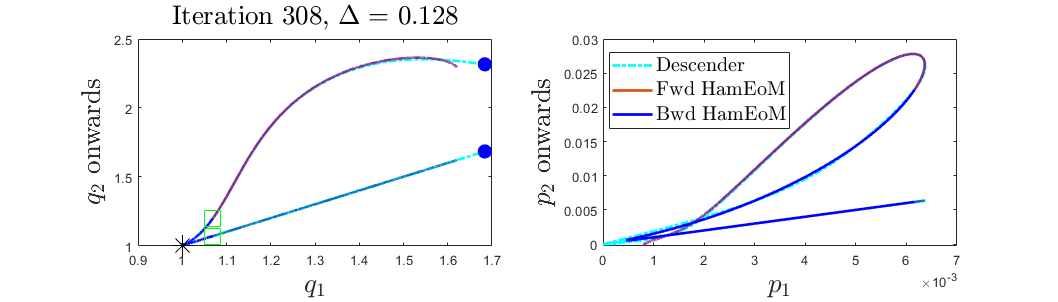

for i = 1:size(TF,2)
    iter = TF(i);
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,iter);
    t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
    save_plot_name = save_plot_name_root + '_HamEoM_'+string(iter)+'.png';
    plotnam = string(iter);
    [a,Ham_traj_for,Ham_traj_back] = Ham_closest_approach_hi_dim(PS_traj,S_traj,t_traj,...
    dHamdp_fun, dHamdq_fun, save_plot_name,1,plotnam);
    
    
end

plotnam = plotnam_old;

### Initialization values

eps_ic 

eps_ic =    0.250000000000000


eps_min 

eps_min =    0.010000000000000


err_thresh 

err_thresh =    0.100000000000000


f0_init 

f0_init =      3


eps_S_thresh 

eps_S_thresh =      1.000000000000000e-07


delta_S_thresh 

delta_S_thresh =      9.999999999999999e-06


delta_S_thresh_eps 

delta_S_thresh_eps =      5.000000000000000e-05


time_uniform_f

time_uniform_f =     45


## Descent summary

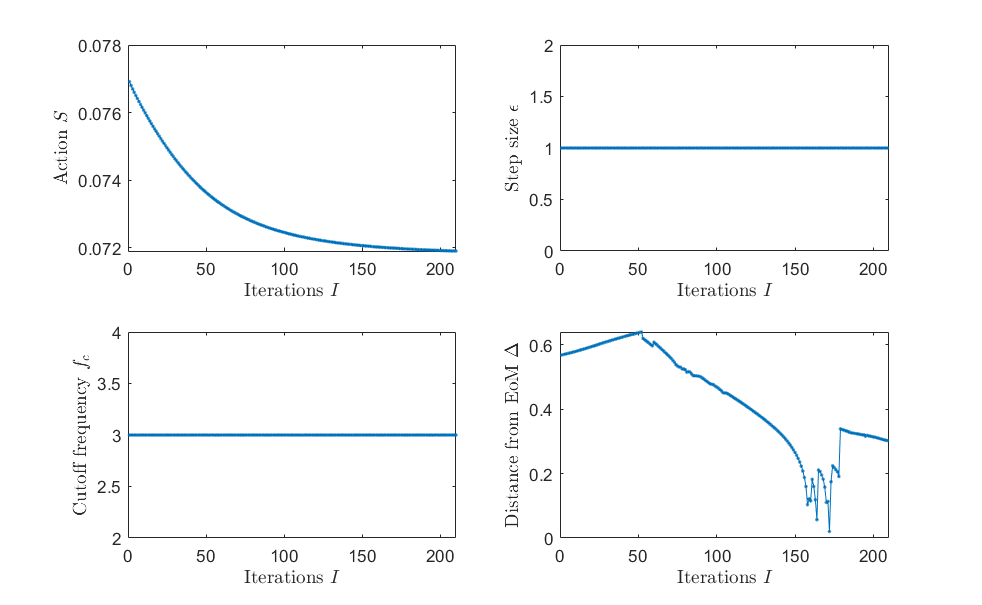


[traj_pts,num_spec] = size(traj);

init_iter = 1;
tot_iter = size(S_arr,1);

%Action
figure()
subplot(2,2,1)
plot(S_arr,'.-','LineWidth',0.75)
ylabel('Action $S$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%epsilon-step size
subplot(2,2,2)
plot(eps_arr,'.-','LineWidth',0.75)
ylabel('Step size $\epsilon$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%cutoff frequency bin
subplot(2,2,3)
plot(f0_arr,'.-','LineWidth',0.75)
ylabel('Cutoff frequency $f_c$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;


%Ham EoM distance frequency bin
subplot(2,2,4)
plot(a_arr,'.-','LineWidth',0.75)
ylabel('Distance from EoM $\Delta$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

x0=0.1;
y0=0.1;
width=26;
height=16;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_action_eps_freq_delta.png';
saveas(gcf,save_plot_name)

[a,b]=min(a_arr);

a = 0.0201

b = 172

## Progress in phase space

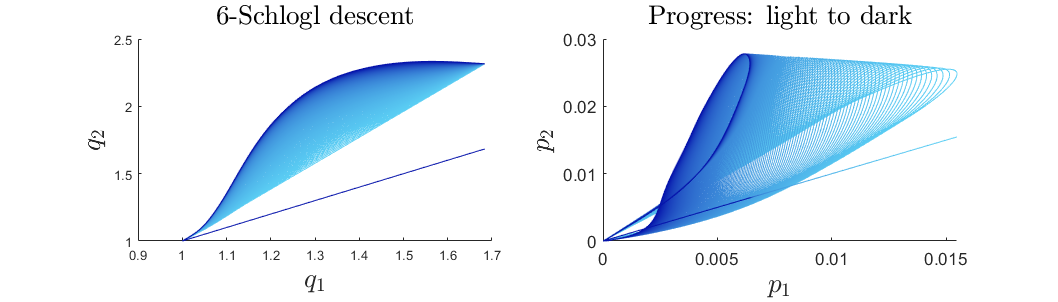

%Trajectories
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));
diter  = 1;
figure()
subplot(1,2,1)
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
xlabel('$q_1$','interpreter','latex','FontSize',20)
ylabel('$q_2$','interpreter','latex','FontSize',20)
title(plotnam+' descent','interpreter','latex','FontSize',20)
hold off
%grid on

%momentum
subplot(1,2,2)
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,num_spec + 1:2*num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
ax=gca;
ax.FontSize = 13;
xlabel('$p_1$','interpreter','latex','FontSize',20)
ylabel('$p_2$','interpreter','latex','FontSize',20)
title("Progress: light to dark",'interpreter','latex','FontSize',20)
hold off

%grid on
x0=0.1;
y0=0.1;
width=28;
height=8;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_descender_progress.png';
saveas(gcf,save_plot_name)

## Plot sudden jump gradients 

### Find spots

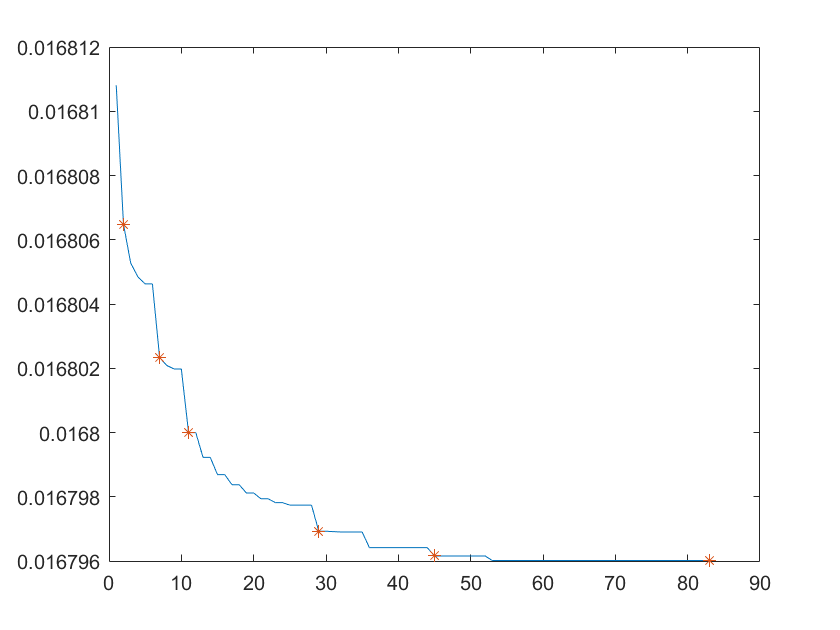

%Find index of sudden jumps of S_arr
%[TF,S1] = ischange(S_arr,'variance','MaxNumChanges',10);
TF = findchangepts(S_arr','MaxNumChanges',4);
 TF = [TF 45 size(S_arr,1)];

figure()
plot(S_arr)
hold on
xran = 1:size(S_arr,1);
plot(xran(TF),S_arr(TF),'*')
hold off

### Plot gradient

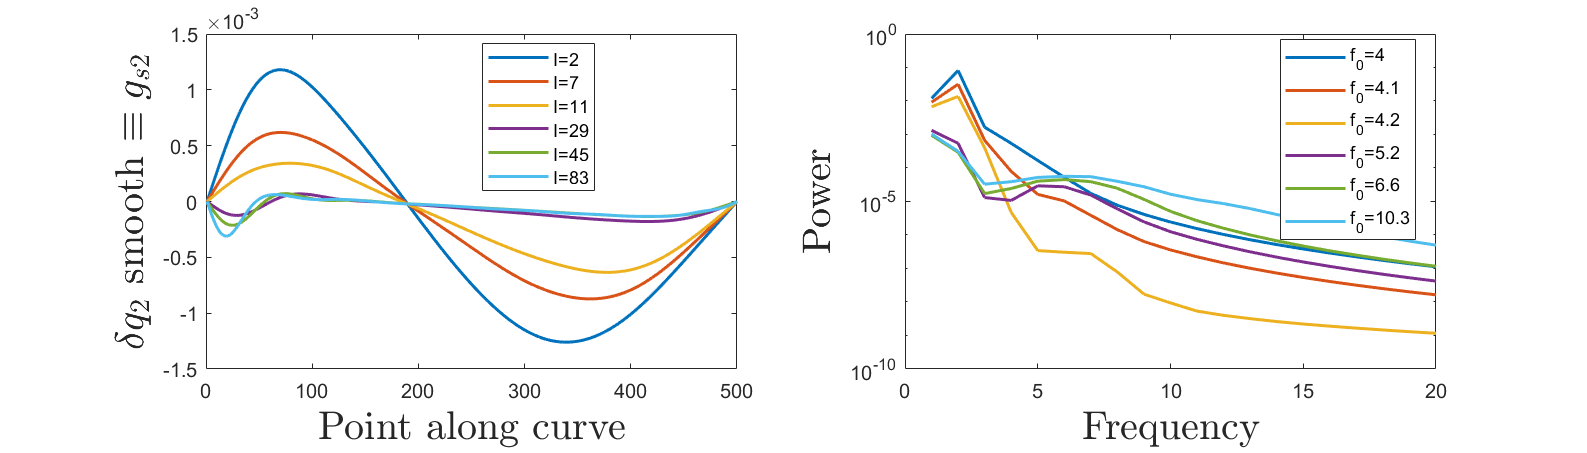

figure()
subplot(1,2,1)
for i = 1:size(TF,2)
    iter = TF(i);
    g_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,iter);
    plot(g_s(:,2),'DisplayName','I='+string(iter),'LineWidth',1.5)
    hold on
end
%grid on
xlabel('Point along curve','Interpreter','latex','FontSize',20)
ylabel('$\delta q_2$ smooth $\equiv g_{s2}$','Interpreter','latex','FontSize',20)
legend('location','best')
%title(plotnam + ' : dim #2')
hold off
%xlim([0 500])

subplot(1,2,2)
for i = 1:size(TF,2)
    iter = TF(i);
    g_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,iter);
    semilogy(abs(fft(g_s(:,2))).^2,'DisplayName','f_0='+string(f0_arr(iter)),'LineWidth',1.5)
    xlim([0 20])
    hold on
end
%grid on
%title('Descent progress')
xlabel('Frequency','Interpreter','latex','FontSize',20)
ylabel('Power','Interpreter','latex','FontSize',20)
legend('location','best')
hold off


x0=0.1;
y0=0.1;
width=28;
height=8;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_g_s_change_2.png';

saveas(gcf,save_plot_name)

plotnam_old = plotnam;
TF = [172]

TF = 172

### Hamilton's EoM

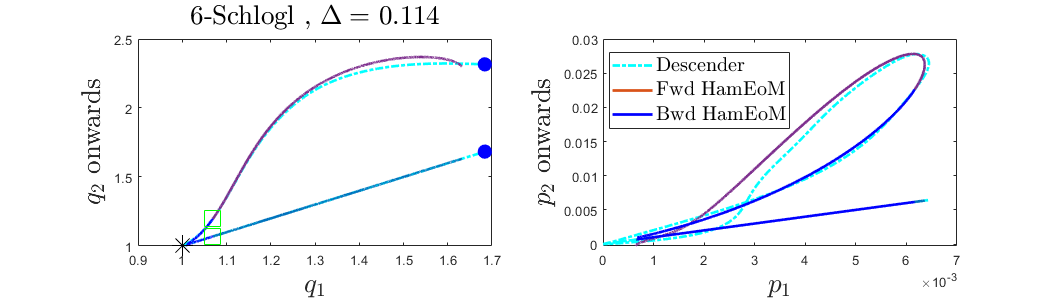

ans = 0.1137

for i = 1:size(TF,2)
    iter = TF(i);
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,iter);
    t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
    save_plot_name = save_plot_name_root + '_HamEoM_'+string(iter)+'.png';
    plotnam = string(iter);
    Ham_closest_approach_hi_dim(PS_traj,S_traj,t_traj,...
    dHamdp_fun, dHamdq_fun, save_plot_name,1,plotnam)
    
end

plotnam = plotnam_old;

save('PS_traj_schlogl_2.mat',"PS_traj")

action_PS_traj(PS_traj)

ans = 0.0168

## Surf plots

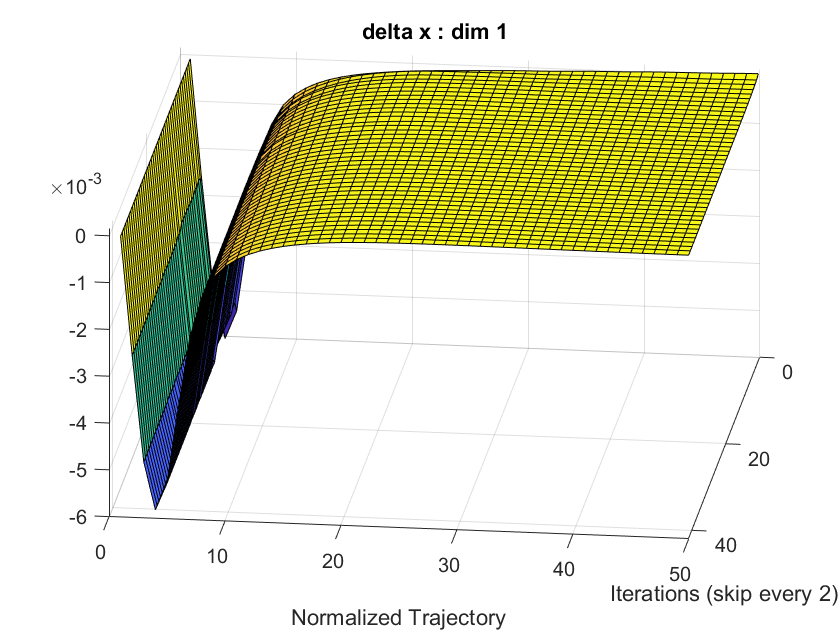

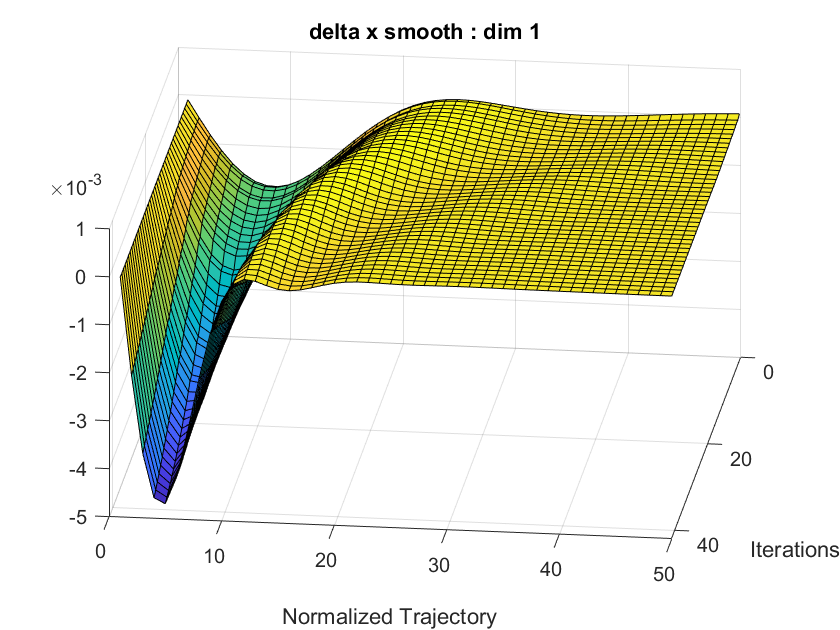

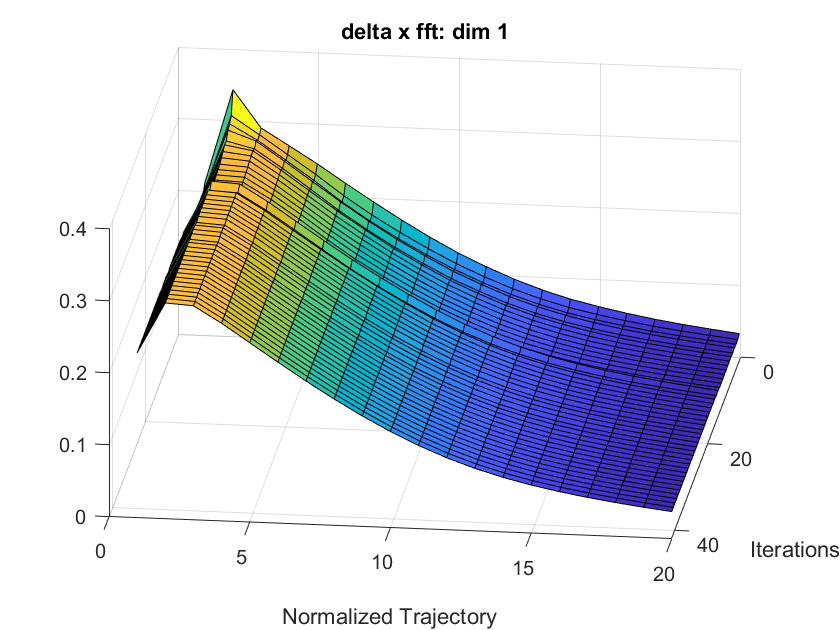

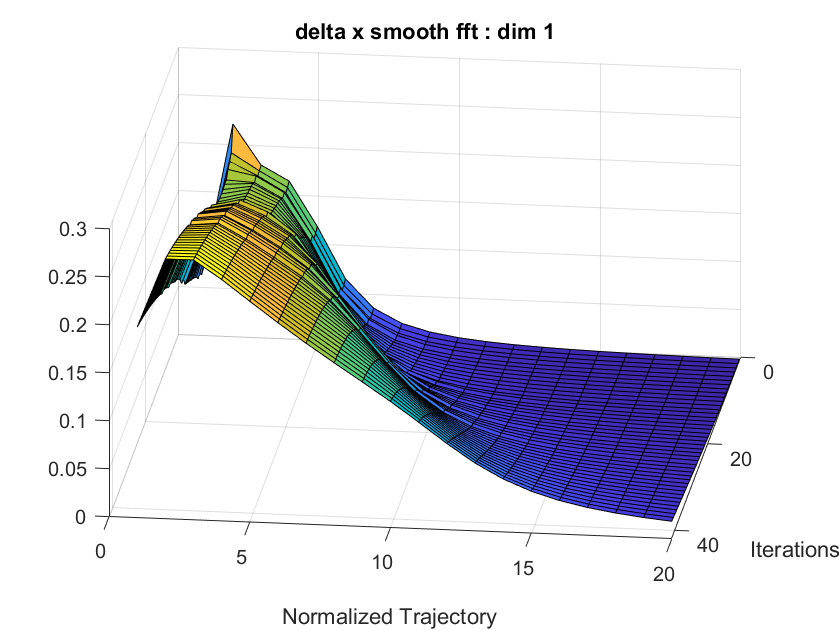

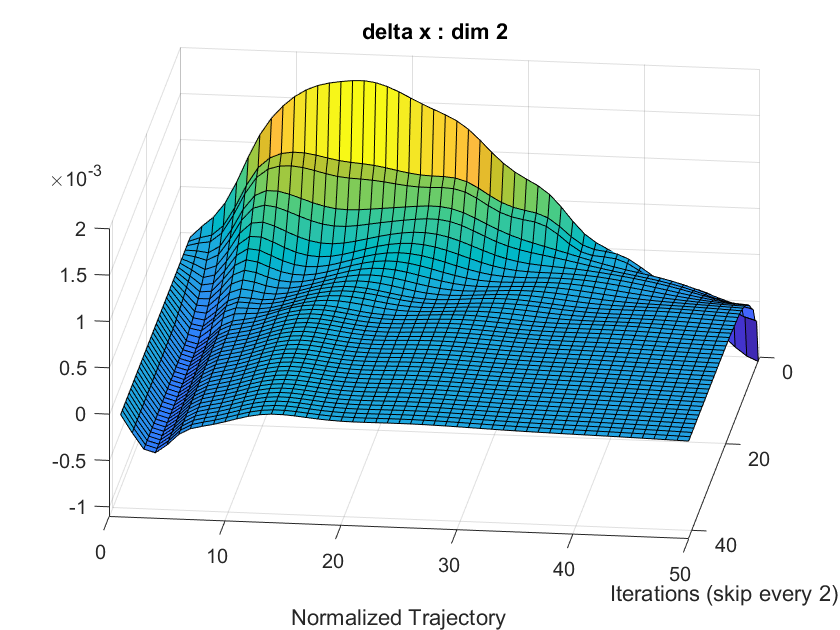

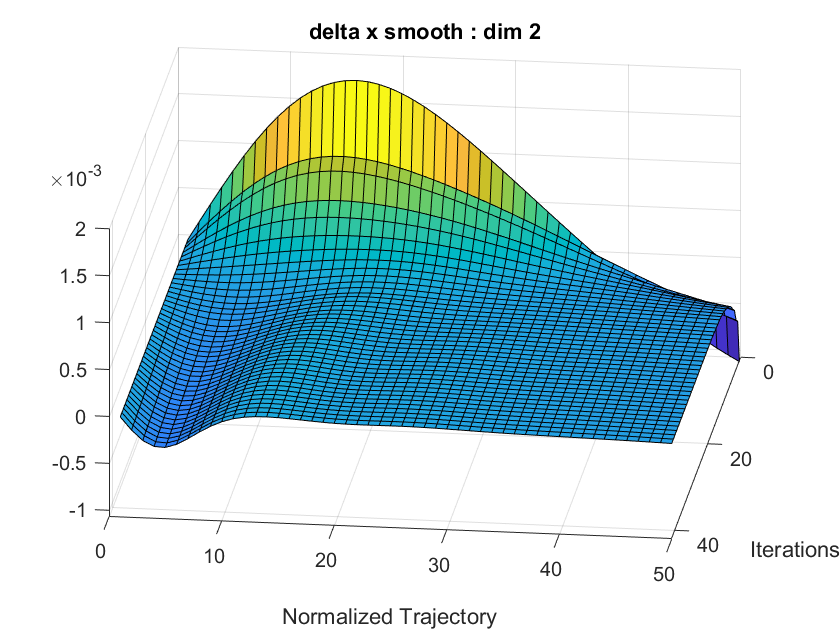

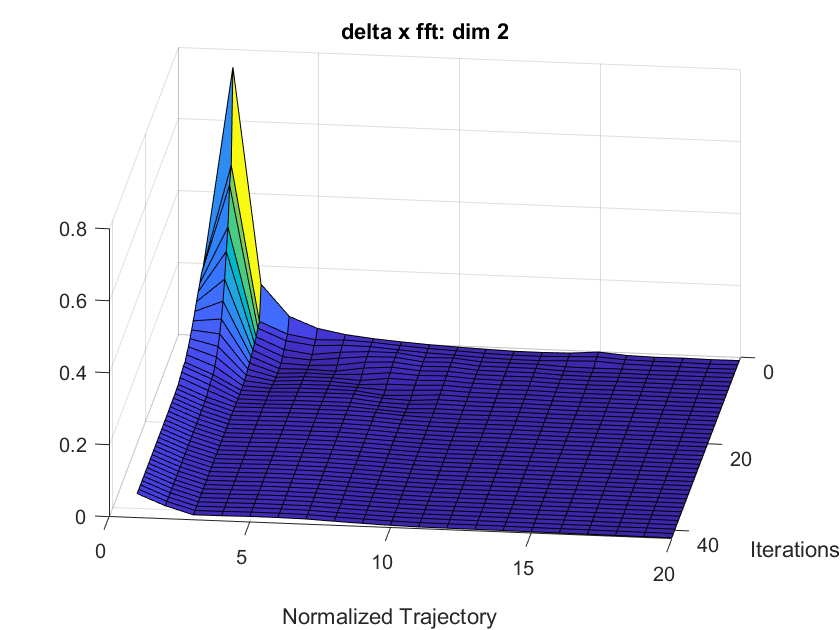

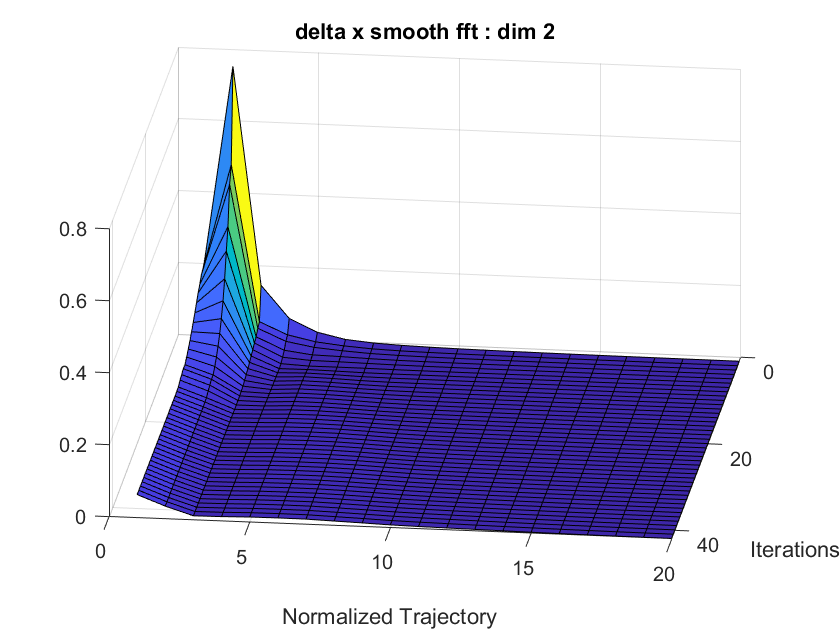

%Surf plots
%Points to skip along trajectory
dtraj = 10;
diter = 2;

traj_pts_indx = 1000;
tot_iter = 83;
init_iter = 1;
%deltax
[deltax_3d, deltax_3d_fft] = surf_input(deltax_arr,num_spec,tot_iter,traj_pt_arr,traj_pts_indx);
[deltax_s_3d, deltax_s_3d_fft] = surf_input(deltax_lp_arr,num_spec,tot_iter,traj_pt_arr,traj_pts_indx);

for i = 1:num_spec
    figure()
    surf(squeeze(deltax_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations (skip every '+string(diter)+')')
    ylabel('Normalized Trajectory')

    figure()
    surf(squeeze(deltax_s_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x smooth : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Normalized Trajectory')

    figure()
    surf(squeeze(deltax_3d_fft(i,1:20,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x fft: dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Normalized Trajectory')

    figure()
    surf(squeeze(deltax_s_3d_fft(i,1:20,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x smooth fft : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Normalized Trajectory')

end

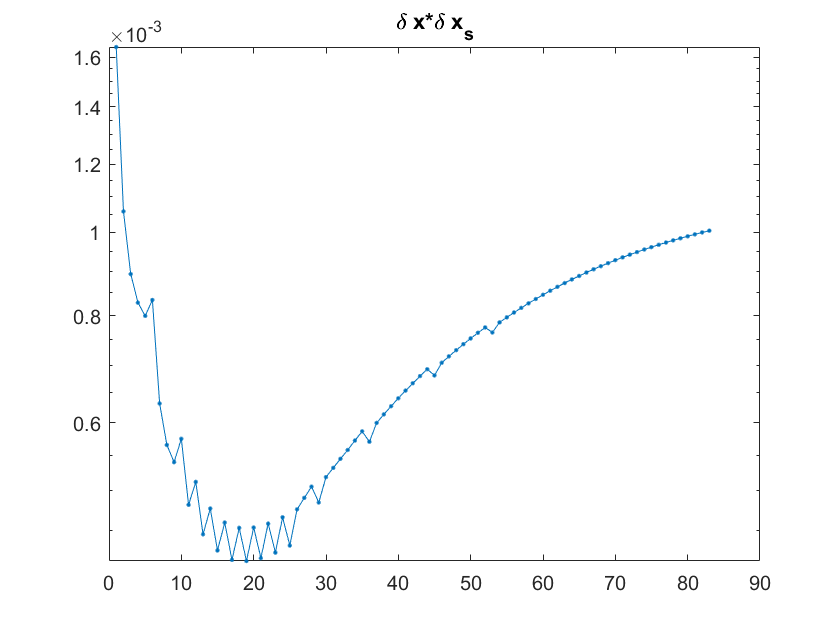


%Plot delta_x^2
delta_S = zeros(tot_iter,1);
for i = 1:tot_iter
    delta_S(i) = sum(squeeze(deltax_3d(:,:,i)).*squeeze(deltax_s_3d(:,:,i)),"all");
end
figure()
semilogy(delta_S,'.-')
title('\delta x*\delta x_s')

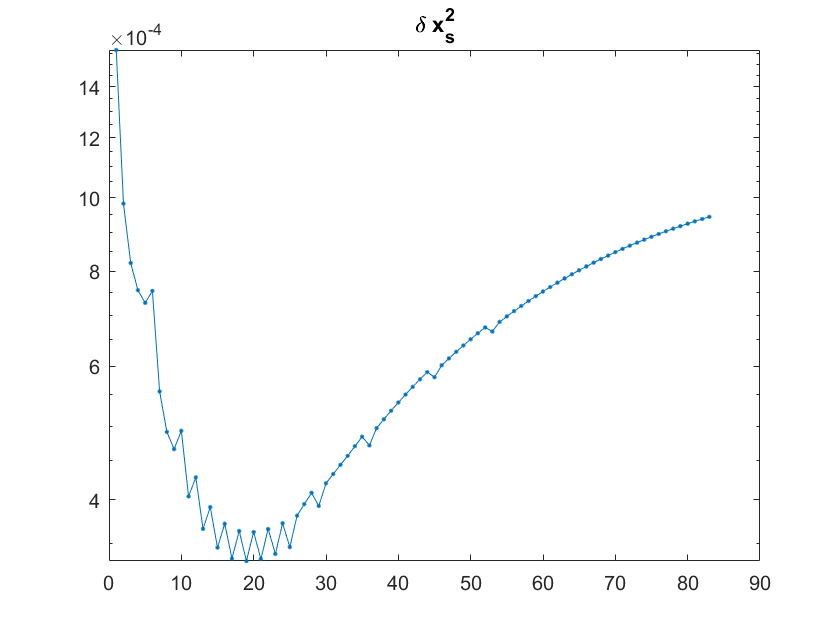


%Plot delta_x_s^2
delta_S = zeros(tot_iter,1);
for i = 1:tot_iter
    delta_S(i) = sum(squeeze(deltax_s_3d(:,:,i)).*squeeze(deltax_s_3d(:,:,i)),"all");
end
figure()
semilogy(delta_S,'.-')
title('\delta x_s^2')

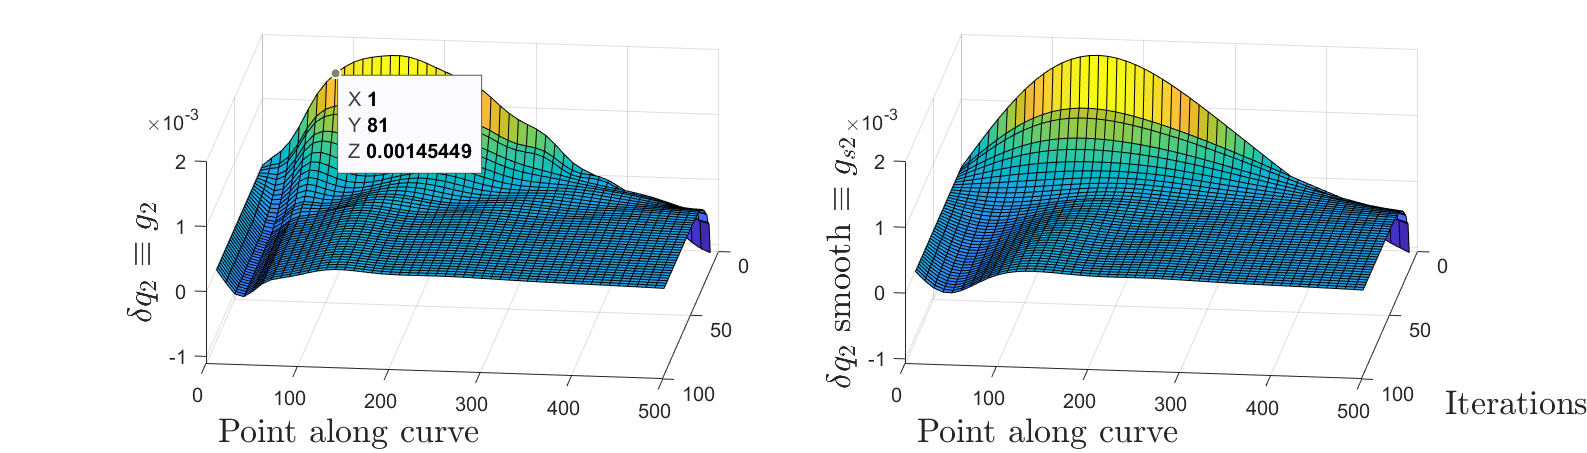

diter = 2;
i=2;
[X,Y] = meshgrid(init_iter:diter:tot_iter,1:dtraj:traj_pts);

figure()
subplot(1,2,1)
Z_mat = squeeze(deltax_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter));
surf(X,Y,Z_mat)
%shading interp
%title(plotnam + ' : \delta q \equiv g ')
zlabel('$\delta q_2$  $\equiv g_{2}$','Interpreter','latex','FontSize',17)

view([97.02 32.46])
ylabel('Point along curve','Interpreter','latex','FontSize',17)

subplot(1,2,2)
Z_mat = squeeze(deltax_s_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter));
surf(X,Y,Z_mat)
%shading interp
zlabel('$\delta q_2$ smooth $\equiv g_{s2}$','Interpreter','latex','FontSize',17)
view([97.02 32.46])
xlabel('Iterations','Interpreter','latex','FontSize',17)
ylabel('Point along curve','Interpreter','latex','FontSize',17)


x0=0.1;
y0=0.1;
width=28;
height=8;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_delta_surf_2.png';

saveas(gcf,save_plot_name)

Plot initial conditions and gradient + smooth gradient 

load("..\Data\Schlogl_1_2_descend_1_2straight_500_11-Jul-2022.mat")

load( "..\Data\Selkov_descend_1_1straight_2500_14-Jul-2022.mat")

PS_traj = PS_arr(1:traj_pts,:);
t_traj = time_arr(1:traj_pts,:);
delta_x = deltax_arr(1:traj_pts,:);
delta_x_s = deltax_lp_arr(1:traj_pts,:);



%Plot PS_traj and save
model_name

model_name = "Schlogl_1_2"

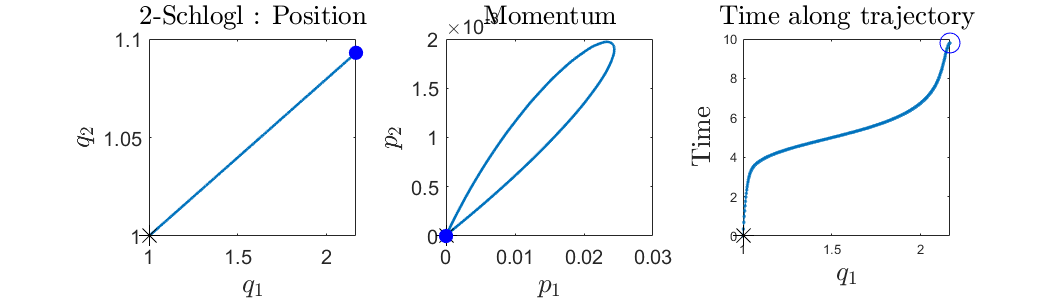

save_plot_name = 'Plots/'+model_name+'_traj_IC.png';
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);

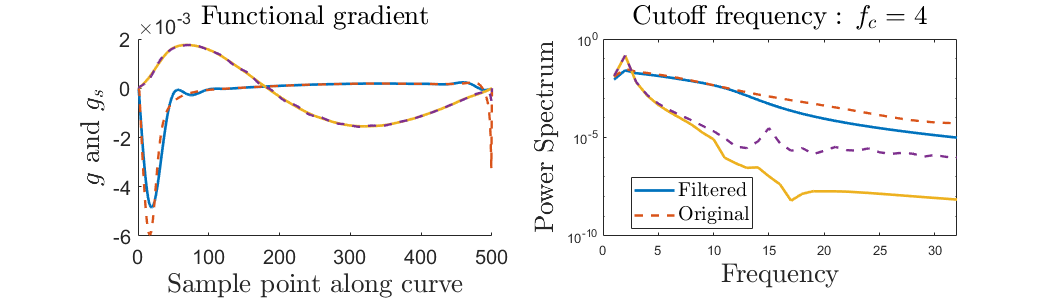


%delta_x_s
delta_x_s =  smooth_traj_butter(delta_x,f0); 
f0 = f0_arr(1);
%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_deltax_IC.png';
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);

## Old stuff

load("..\Data\Schlogl_1_2_descend_1_2straight_2000_11-Jul-2022.mat")
a_arr = [];
max_iter = size(S_arr,1);



for iter = 1:max_iter
    PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
    S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
    t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);

    a_min = Ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,0,plotnam);
    a_arr = [a_arr; a_min];
end

iter = 56;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);

a_min = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam);


figure()
plot(a_arr)
grid on

figure()
plot(a_arr,'.-')
xlim([1 56])
grid on

save("..\Data\Schlogl_1_2_descend_1_2straight_2000_11-Jul-2022.mat")


figure()
plot(traj_pt_arr)


%Trajectories
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));
diter  = 1;
figure()
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
xlabel("q_1")
ylabel("rest")
title("Descender progress: light blue to dark blue ")
hold off
grid on